**Kvantisering og kvantiseringsfejl ved A/D-konvertering**

Det primære formål er at følge op på kvantisering med fokus på Signal-Noise-Ratio (SNR).

opengl hardware
close all
clear
clc

## **1. Model for øvelsen**

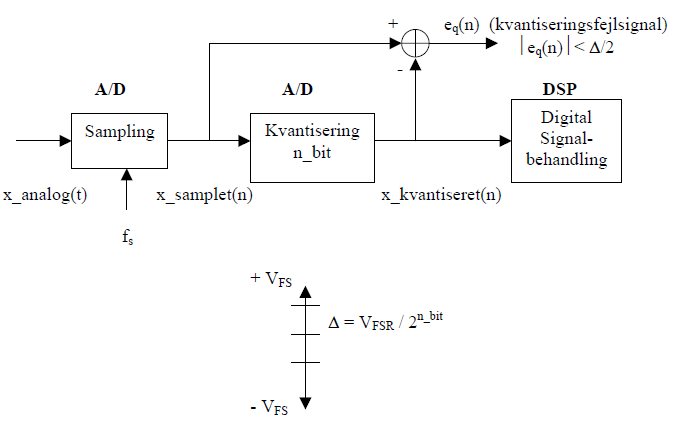

## **2. Kvantisering og kvantiseringsfejl**

**Definition af samplet signal:**

fs = 10000;
Ts = 1/fs;
N = 500;
n = 0:N-1;
f1 = 117; %Tilfældig værdi, der ikke er divisor i fs
VFS = 1; %Full-scale-værdi for analogt signal
VFSR = 2*VFS; %Full-scale-range for A/D-konverteren
x_samplet = VFS*sin(2*pi*f1*n*Ts);

**Kvantisering af samplet signal:**

Der vælges opløsning på 3 bit, idet det er nemmere at forstå, selvom det er urealistisk lavt.

n_bit = 3;

Trinstørrelse (svarende til LSB)

delta = VFSR/(2^n_bit)

delta = 0.2500

Denne er i dette tilfælde 0.25.

Signalet kvantiseres i intervallet -VFS til +VFS

x_kvantiseret = delta * round(x_samplet/delta);

Kvantiseringsfejl beregnes

eq = x_samplet - x_kvantiseret;

**Plot af samplet og kvantiseret signal samt kvantiseringsfejl i tidsdomænet:**

subplot(3,1,1)
stem(n,x_samplet,'.')
subplot(3,1,2)
stem(n,x_kvantiseret,'.')
subplot(3,1,3)
stem(n,eq,'.')

Kvantiseringsfejlen er nogenlunde tilfældig og op til delta/2. Det er tydeligt fra kvantiseringsgrafen, at der sker en afrunding.

**Beregning og plot af kvantiseringsfejl i frekvensdomænet:**

For at se, om fejlen kan opfattes som hvid støj, altså at den består af alle frekvenser, beregnes frekvensspektret

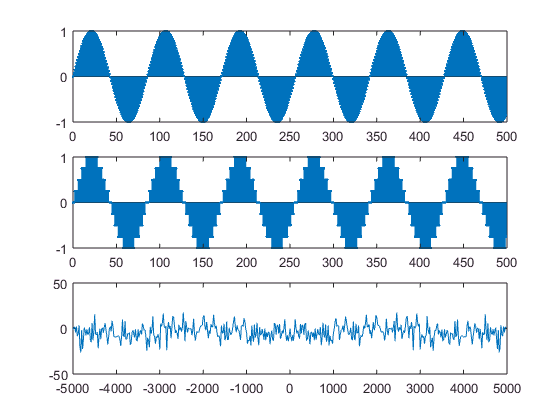

Eq = fftshift(fft(eq,N));
k = (-N/2):(N/2-1);
f = k*fs/N;
plot(f,20*log10(abs(Eq)))

Ved at se på plottet kan det bekræftes, at det er hvid støj.

**Beregning og kontrol af RMS-værdi og signal/støj-forhold for kvantiseringsfejl:**

Jvf. teorien er middelværdien af kvantiseringsfejlsignalet lig 0, og RMS-værdien er e_q,rms = delta/sqrt(12)

mean(eq) %Middelværdien af kvantiseringsfejlen

ans = 0.0020

eq_rms = std(eq) %RMS-værdien af kvantiseringsfejlen

eq_rms = 0.0677

Der er en lille afvigelse, der vil gå mod 0, hvis der var uendelig mange samples.

Det bedste tilfælde for signal/støj-forholdet findes, når A/D-konverteren anvender hele udstyringsområdet fra -VFS til +VFS. Denne værdi beregnes som SNR_Q,best = 6.02*n_bit + 1.78 [dB]

Kontrol:

x_samplet_rms = std(x_samplet)

x_samplet_rms = 0.7118

SNR_Qudr = 20*log10(x_samplet_rms / eq_rms)

SNR_Qudr = 20.4345

SNR_Qbest = 6.02*n_bit + 1.78

SNR_Qbest = 19.8400

Der er altså en forskel på under 1 dB.